# Sistemas Realimentados - 2023/2

## Nome: Dionatas Santos Brito

## Data limite para entrega: 8/11, 6h

**Importante lembrar:**

- Entrega após a data/horário acima: a nota será multiplicada por $1-e^{-30/h}$, onde h são as horas em atraso (Exemplo: 24h, multiplica por 0.71).

- Não é recebido por email

- Cabe a vocês garantir que o documento entregue é um arquivo pdf legível, e que não foi entregue com erro. Para isto, basta depositar e abrir para conferir.

- Código é apenas uma informação complementar, e não é considerada parte da solução para fins de avaliação.

- Caso não haja tempo de fazer todo o trabalho, entreguem no prazo o que estiver pronto.

## Trabalho 4 - Análise da resposta em frequência


I=8; % Seu valor de I
[nyq1,nyq2]=ini_t4(I);
datetime('now')

ans = datetime
   08-Nov-2023 03:44:37


## Atividade 1: Análise de gráficos de Bode

O gráfico de Bode abaixo contém ganhos, polos e zeros, todos afastados de pelo menos uma década.

**1.1 Obtenha a função de transferência no formato **$G(s)=K\frac{(1+sz_1)(1+sz_2)...}{(1+sp_1)(1+sp_2)...}$** e refaça o gráfico de Bode para verificar se está igual ao fornecido.**

Análise:

**Polos e Zeros**

De acordo com a imagem, a fase se inicia em 90° que é um idicativo para um polo na origem. 

Ao se passar 45° desse polo se dá em 135° oque corresponde a frequência 10°^-1 seria onde estaria o próximo polo (de forma aproximada)

Uma decáda depois, houve uma leve subida no módulo e na fase, oque configura um zero.

Após uma decáda, o módulo diminui e a fase aumenta, esse comportamento se repete até o 270°, oque se explica pela presença de dois polos (um em cada decada)

Sendo assim temos  1 polo e 3 zeros no SPD, localizado em:

Zero: -1

Polo:  -0.1, -10, -100

 
$$G(s)=K\frac{(s+1)}{(s+0,1)(s+10)(s+100)}$$


**Ganho**

O Ganho se dá pela fórmula:


$$\textrm{Ganho}->20\log_{10\;} \;\left(G\left(\textrm{jw}\right)\right)\Rightarrow \;100=20\log_{10} \left(x\right)\Rightarrow {10}^{\left(\frac{100}{20}\right)} =100000$$


%Ganho
K_MODEL= 100000;
s_12= 0.2;
Gain = (K_MODEL*(s_12*(s_12+1)*(s_12+100)*(s_12+1000))/(s_12+10))

Gain = 2.3581e+08


%Bode com ganho 
s=tf('s');
G_MODEL = (s+1)/(s*(s+0.1)*(s+10)*(s+100));
G1=Gain*G_MODEL

G1 =
 
        2.358e08 s + 2.358e08
  ----------------------------------
  s^4 + 110.1 s^3 + 1011 s^2 + 100 s
 
Continuous-time transfer function.
Model Properties


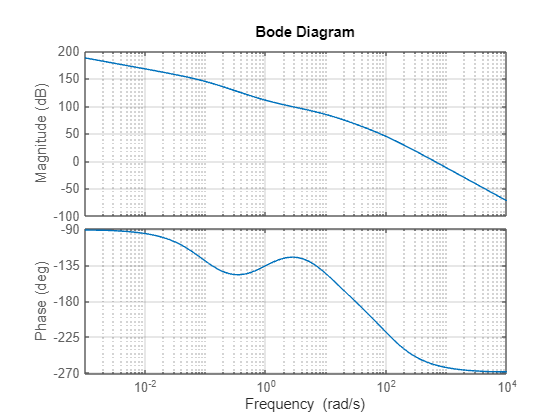

bode(G1)
grid;

**1.2 Obtenha as margens de fase e de ganho.**

Margem de Fase (MF):

- A margem de fase é uma medida da estabilidade de um sistema realimentado.

- Ela representa a quantidade de defasagem (em graus) que o sistema pode suportar antes de se tornar instável.

- Quanto maior a margem de fase, mais estável é o sistema.+

- Ela é obtida verificando a frequêcia na qual a o módulo cruza o eixo de 0dB

- Qual o valor requerido para que a curva de fase de +-180dB na frequência em que a curva do módulo é de 0 dB.

Margem de Ganho (MG):

- A margem de ganho é a medida relacionada à magnitude do ganho do sistema.

- Ela indica o quanto o ganho do sistema pode ser aumentado antes de o sistema se tornar instável.

- Uma margem de ganho maior significa uma maior robustez contra variações no ganho do sistema.

- Ela é obtida verificando a frequêcia na qual a fase cruza o eixo de 180°

- Qual ganho requerido para que a curva de ganho seja de 0dB na frequência em que a fase é de +-180°

Análise:

Observando a imagem/o bode gerado por G_MODEL, temos que:

Para a margem de fase:   

Se deve olhar em qual frequência está o 0dB no módulo, e  seguindo para a fase e o quanto falta pra 180°.

MF = (180° - oque falta p/180°)

MF = 180° - 259° = 79° aproximadamente

Para a margem de ganho: 

 MG: Em quantos dB cruza o 180°, ou seja, o quanto falta pra chegar em 0dB

 MG = 67° aproximadamente.

Para fins de verificação, segue abaixo o diagrama de ganho e fase gerados pelo matlab onde podemos verificar que deu resultados próximos.

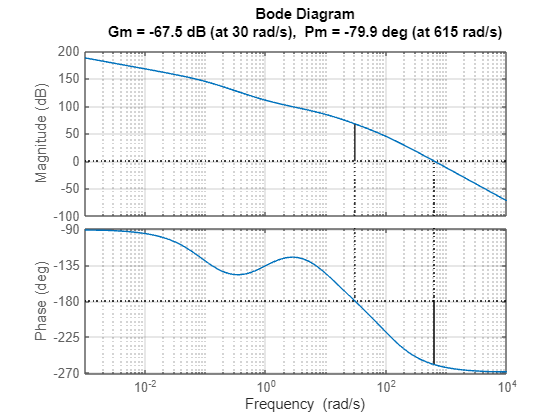

%Margem de fase e ganho
margin(G1)
grid;

**Figura base para a questão 1)**

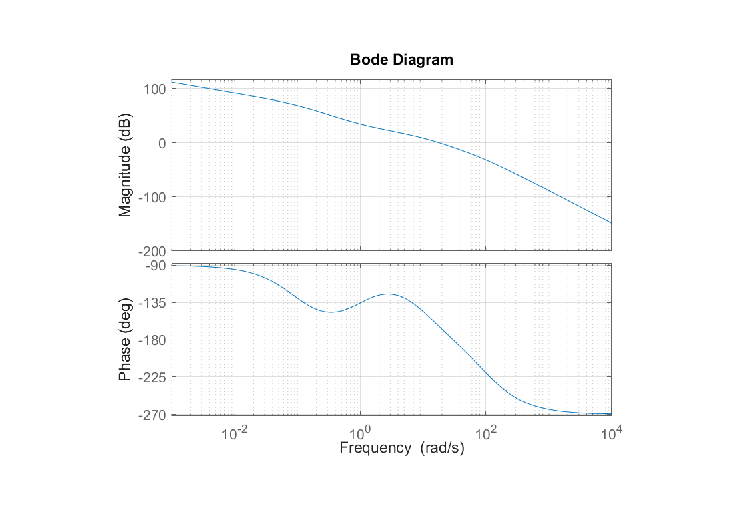

figure
imshow('fig1.png');

## Atividade 2: Critério de Nyquist

Seja o gráfico de Nyquist abaixo de $G(s)=\frac{K}{s(s+a)(s+b)}$, $a>0, b>0$. desenhado com $K=1.$

nyq1

nyq1 = -1.8000

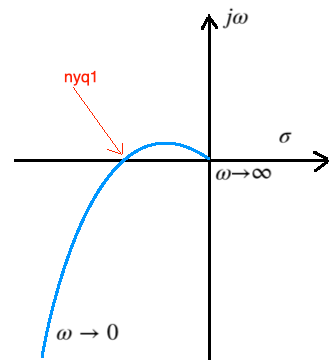

**2.1 Obtenha as condições para estabilidade usando o critério simplificado de Nyquist. Escreva aqui, ou faça à mão, digitalize e coloque aqui como figura (imshow). **

** Analisando o gráfico polar a cima podemos dizer que: **

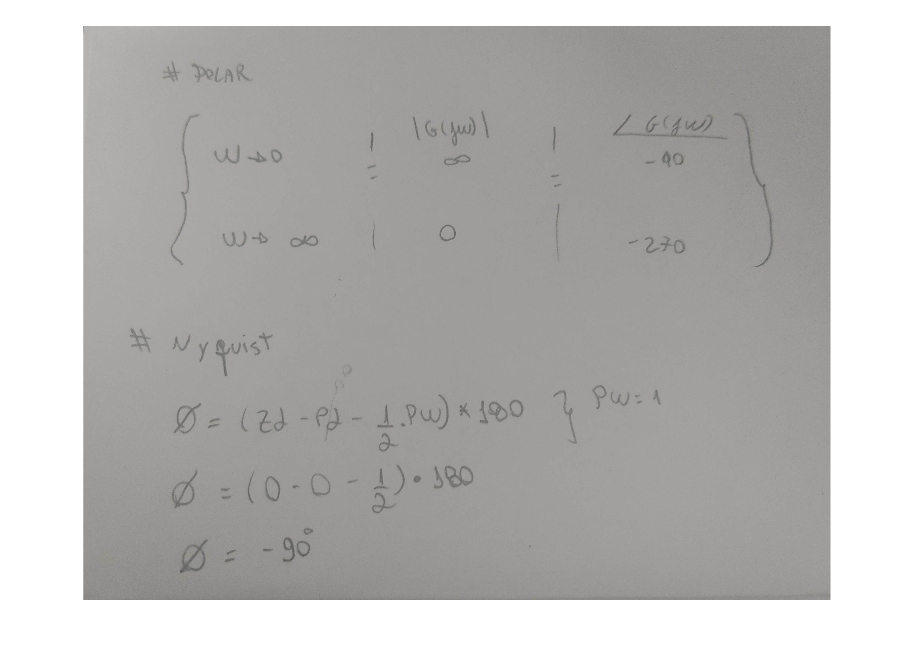

figure
imshow('q21.jpg');

Análise:

Quando $\omega \to 0\;$ o módulo tende ao infinito e a fase em -90° (por causa do polo na origem)

Quando $\omega \to \infty \;$ o módulo tende a zero e a fase tende a -270 (por causa do acrescimdo de 2 polos no SPE  em que cada um atrasa -90)

E segundo o critério de Nyquist, $\phi =-90\degree$

Dito isso, ao comparar ambos resultados se tem que ao fazer Zd =0, resultou em -90° que é diferente do ângulo encontrado na análise gráfica que implica em um Zd diferente de zero.


$$\phi=(Z_d-P_d-\frac{P_\omega}{2})180^o$$



$$\begin{array}{l}
+270=\left(\mathrm{Zd}-0-\frac{1}{2}\right)*180\\
+270=\mathrm{Zd}*180-90\\
\frac{360}{180}=\mathrm{Zd}\\
\mathrm{Zd}=2
\end{array}$$


Ou seja, o Zd é diferente de zero e além disso, o valor de nyq1 é igual a -1.8 que cobre o ponto de -1. Portanto é Instável.

**2.2 Obtenha os valores de **$K\in[-\infty, \infty]$** para que esse sistema seja estável, esboçando o gráfico de Nyquist para K negativo.**

Para obter esses valores, precisamos encontrar o quanto que se deve  multiplicar o K para cruzar o -1, ou seja, que o ângulo do fasor seja de -90° e que esteja antes do ponto  -1 no eixo real. Esse cruzamento ocorrerá quando 

$K=\frac{1}{\mathrm{nyq1}}$  e o valor de K deve esta dentro  $0<K<\frac{1}{\mathrm{nyq1}}$

nyq1

nyq1 = -1.8000


Kx= 1/nyq1

Kx = -0.5556


$$\begin{array}{l}
\\
|K*\mathrm{nyq1}|<|\left(-1\right)|\\
\\
|K|>|\frac{1}{\mathrm{nyq1}}|\\
\\
|K|>|-0\ldotp 5556|
\end{array}$$


Dito isso, quando o K é igual a `0.5556` a função fica marginalmente estável e quando ultrapassa dele, ela se torna instável. Logo os valores de K para o sistema ser estável é K menor que  0.5556 (0< K < 0.5556)

Para obter o gráfico negativo, é necessário adicionar 180° e em relação a estabilidade de nyquist, ela não se altera

 Gráfico de Nyquist para K negativo:

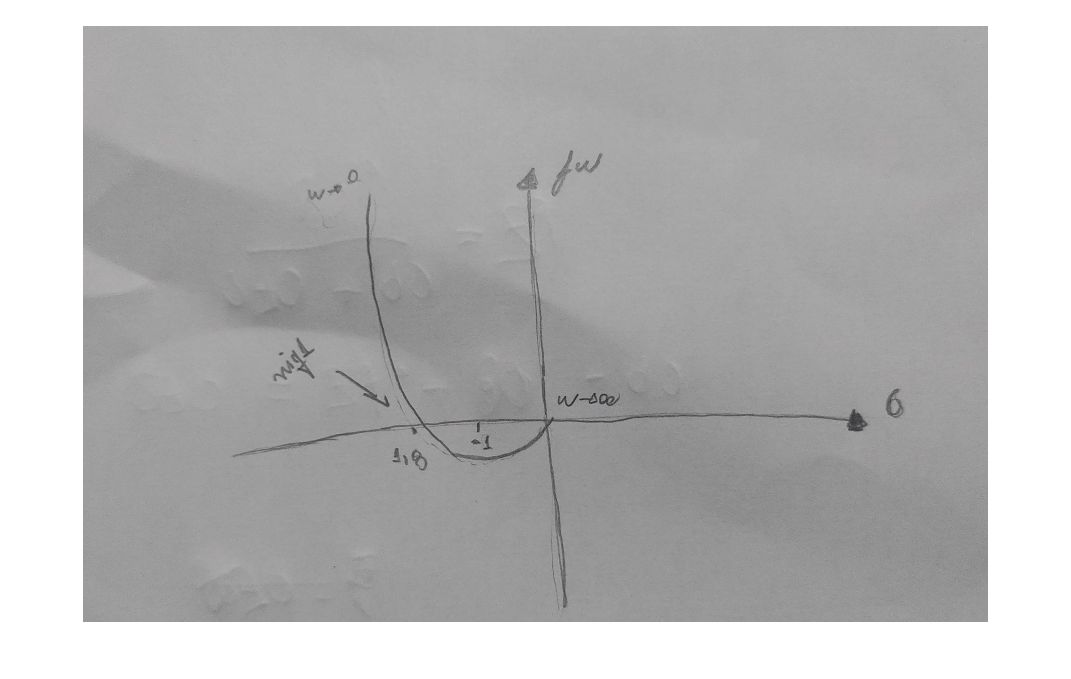

figure
imshow('q22.jpg');

**Seja agora o gráfico de **$G(s)=\frac{K(s+a)^2}{s^3}$**, **$a>0$**, desenhado com **$K=1.$

nyq2

nyq2 = -2.9000

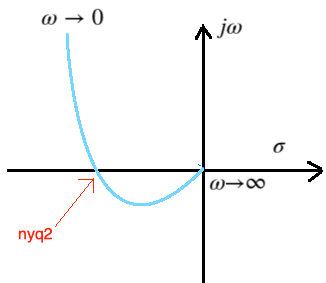

**2.3 Obtenha as condições para estabilidade usando o critério simplificado de Nyquist. Escreva aqui, ou faça à mão, digitalize e coloque aqui como figura. **

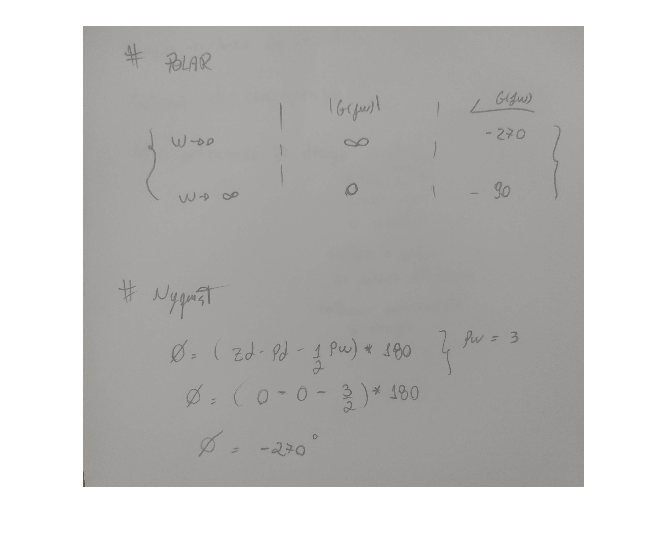

figure;
imshow('23.jpg');

Quando $\omega \to 0\;$ o módulo tende ao infinito e a fase em -270° (por causa dos 3 polos na origem)

Quando $\omega \to \infty \;$ o módulo tende a zero e a fase tende a- 90 (por causa da presença de 2 zeros no semi  plano esquerdo (SPE), pois cada zero irá aumentar o angulo em + 90°)

E segundo o critério de Nyquist, $\phi =-270\degree$

Dito isso, ao comparar ambos resultados se tem que ao fazer Zd =0, resultou em -270° que é diferente do ângulo encontrado na análise gráfica que implica em um Zd diferente de zero.


$$\phi=(Z_d-P_d-\frac{P_\omega}{2})180^o$$



$$\begin{array}{l}
-90=\left(\textrm{Zd}-0-\frac{3}{2}\right)*180\\
-90=\textrm{Zd}*180-270\\
\frac{\left(270-90\right)}{180}=\textrm{Zd}\\
\textrm{Zd}=1
\end{array}$$


Ou seja, o Zd é diferente de zero e além disso, o valor de nyq1 é igual a -2.9 que cobre o ponto de -1. Portanto é Instável.

**2.4 Obtenha os valores de **$K\in[-\infty, \infty]$** para que esse sistema seja estável.**

Para obter esses valores, precisamos encontrar o quanto que se deve  multiplicar o K para cruzar o -1, ou seja, que o ângulo do fasor seja de -270° e que cruze o lado esquedo do ponto  -1 no eixo real. Esse cruzamento ocorrerá quando 

$K=\frac{1}{\textrm{nyq1}}$  e o valor de K deve esta dentro  $0<K<\frac{1}{\mathrm{nyq1}}$


Ky= 1/nyq2

Ky = -0.3448


$$\begin{array}{l}
\\
|K*\mathrm{nyq2}|<|\left(-1\right)|\\
\\
|K|>|\frac{1}{\mathrm{nyq2}}|\\
\\
|K|>|-0\ldotp 3448|
\end{array}$$


Dito isso, quando o K é igual a 0.3448 a função fica marginalmente estável e quando ultrapassa dele, ela se torna instável. Logo os valores de K para o sistema ser estável é K menor que -0.3448 (K < 0.3448)

## Atividade 3: Efeito do ganho na estabilidade** relativa.  **

**3.1 Use o método do lugar das raízes para ver o efeito do ganho nas margens de fase e ganho usando G1 da atividade 1, comparando o efeito do ganho sobre o amortecimento e sobre a margem de fase. Dica: rltool permite ver o LR (amortecimento) e gráfico de Bode (Margens)**.

%para o método do lugar das raízes utilizarei o rltool
G1

G1 =
 
        2.358e08 s + 2.358e08
  ----------------------------------
  s^4 + 110.1 s^3 + 1011 s^2 + 100 s
 
Continuous-time transfer function.
Model Properties


**Análise com Nyquist **

Para fins de análise irei plotar o nyquist de G1 separadamente e após isso irei variar para um ganho menor e para um ganho muito maior afim de ver a diferença da variação

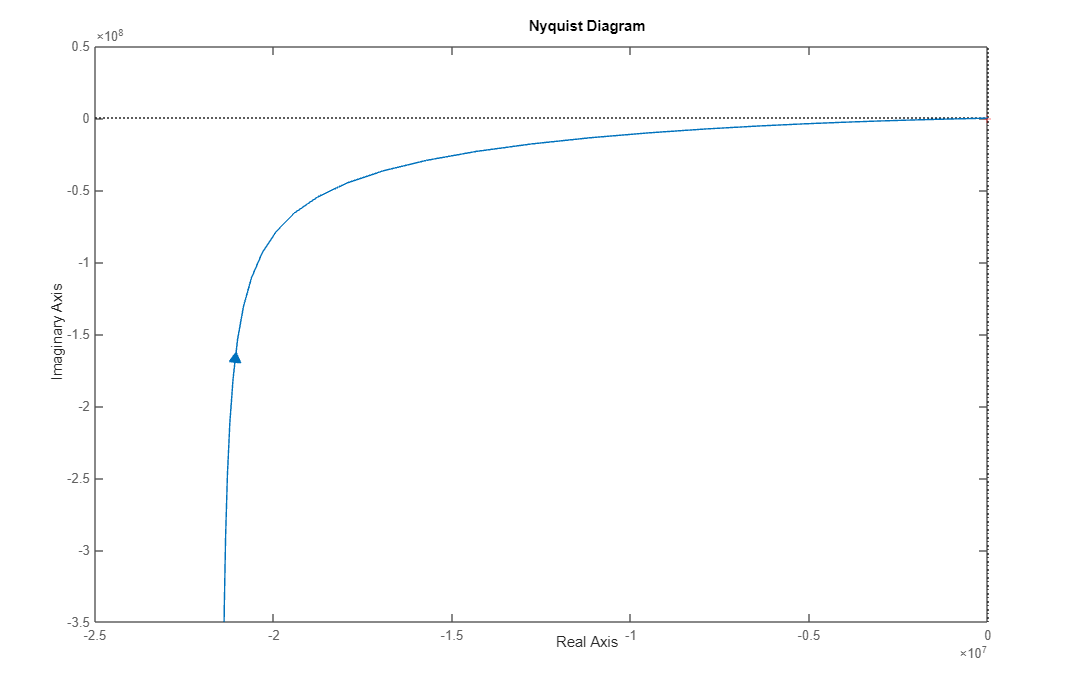

%nyquist separadamente
h=nyquistplot(G1);
set(h,'ShowFullContour','off');

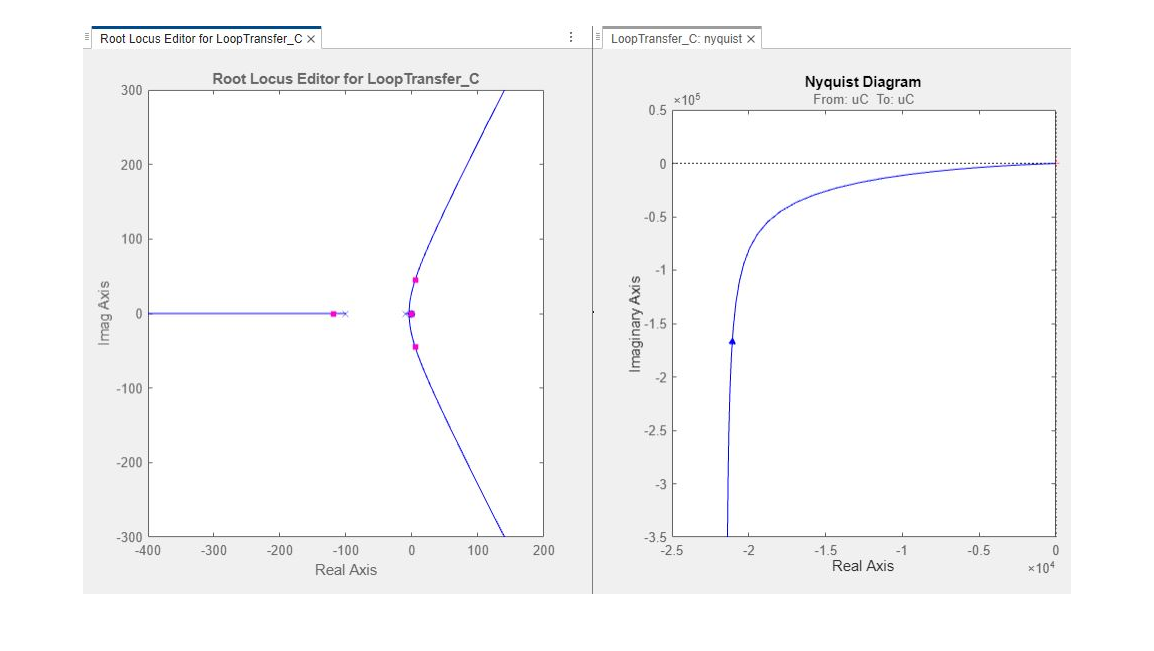


%nyquist com um ganho K menor 
figure;
imshow('nyquist-menor.jpg');

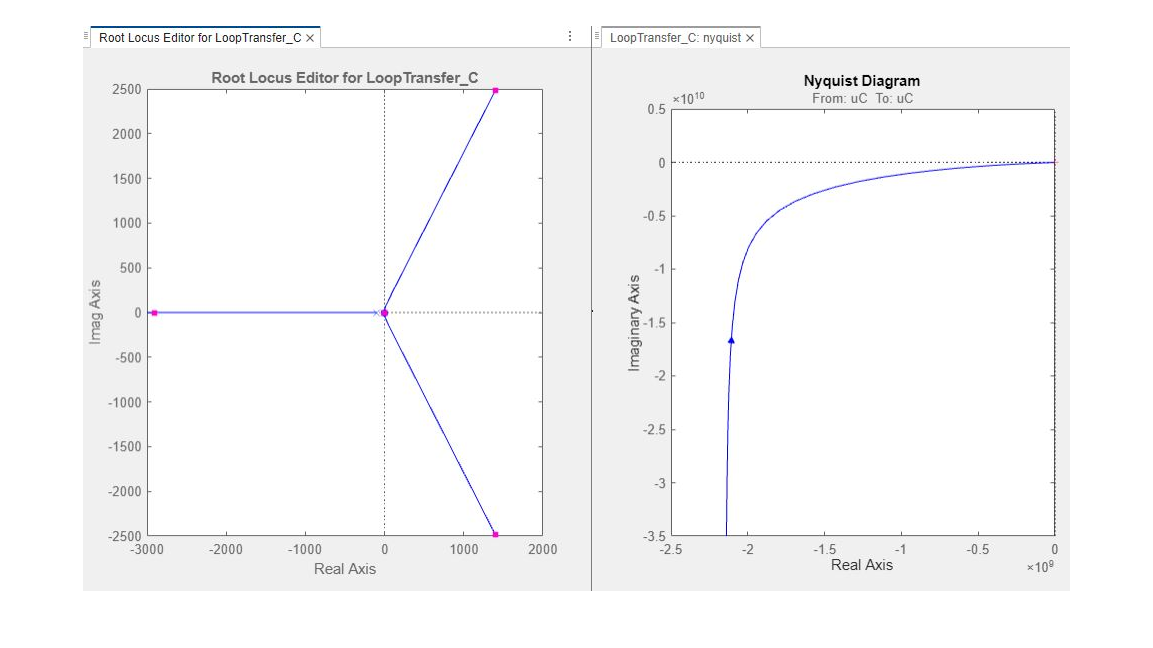



%nyquist com um ganho K maior
figure;
imshow('nyquist-maior.jpg');

**Margem de fase e de ganho + Armotecimento (**$\zeta$**)**

Para fins de análise assim como na anterior, irei plotar a margem de  G1 separadamente e após isso irei variar para um ganho menor e para um ganho muito maior afim de ver a diferença da variação

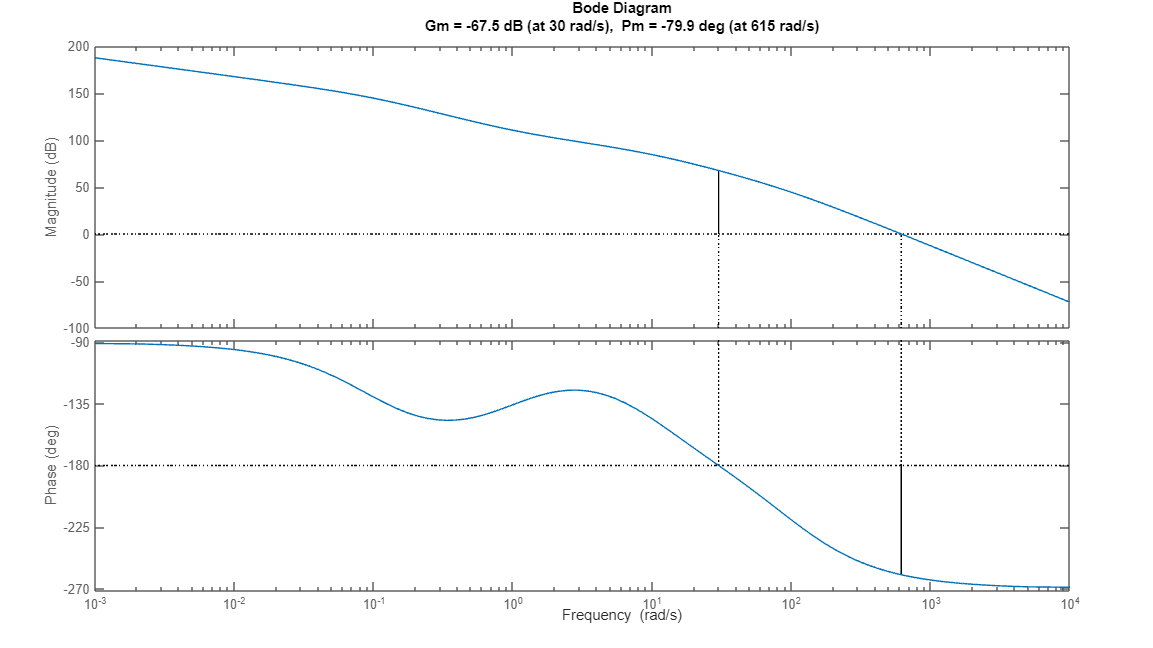

%margem de ganho e de fase (K = 1)
margin(G1)

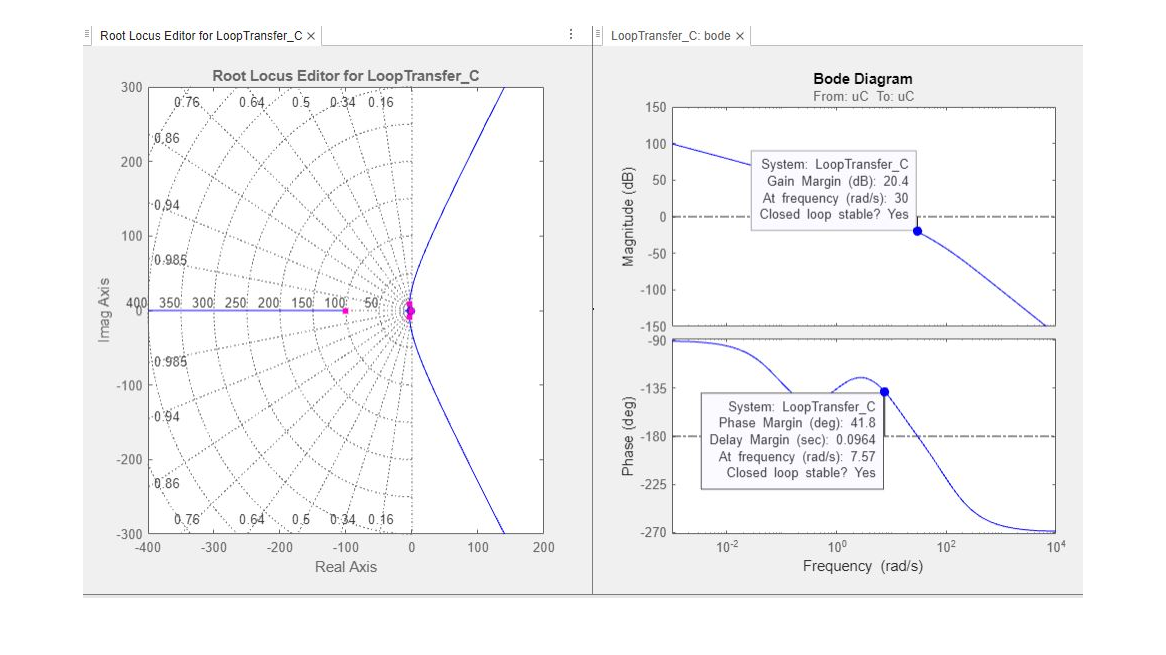

%margens de ganho e fase com um ganho K menor (K = 0.00004) 4*10^-5
figure;
imshow('K-menor.jpg');

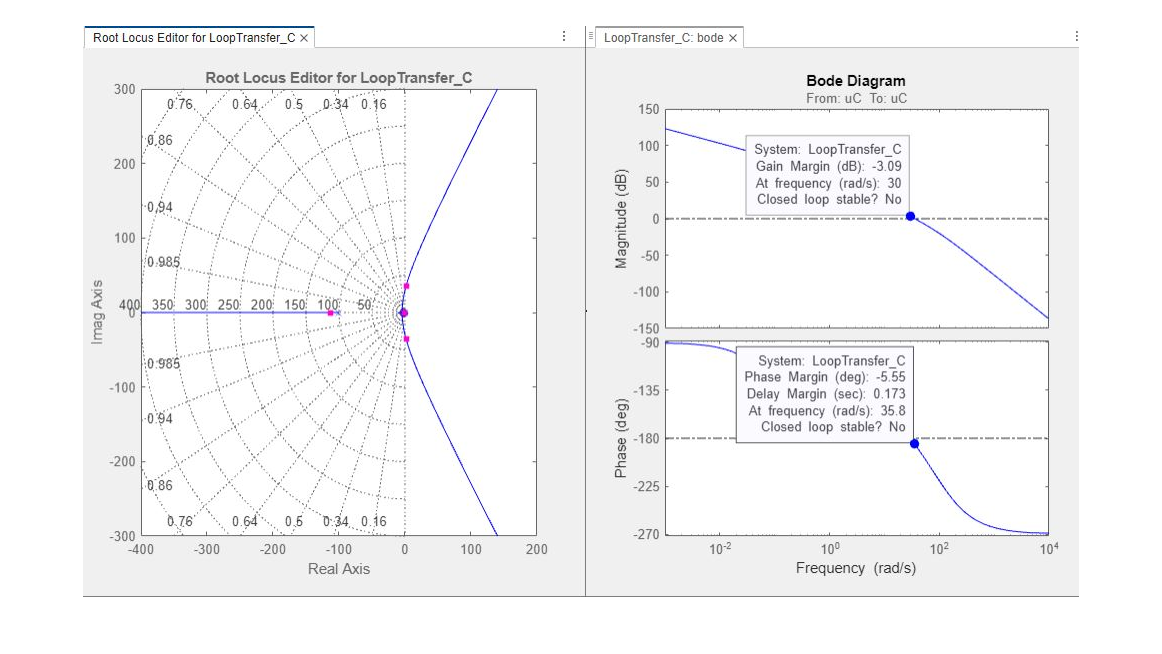


%margens de ganho e fase com um ganho K maior (K = 0.0006) 6*10^-4
figure;
imshow('K-maior.jpg');

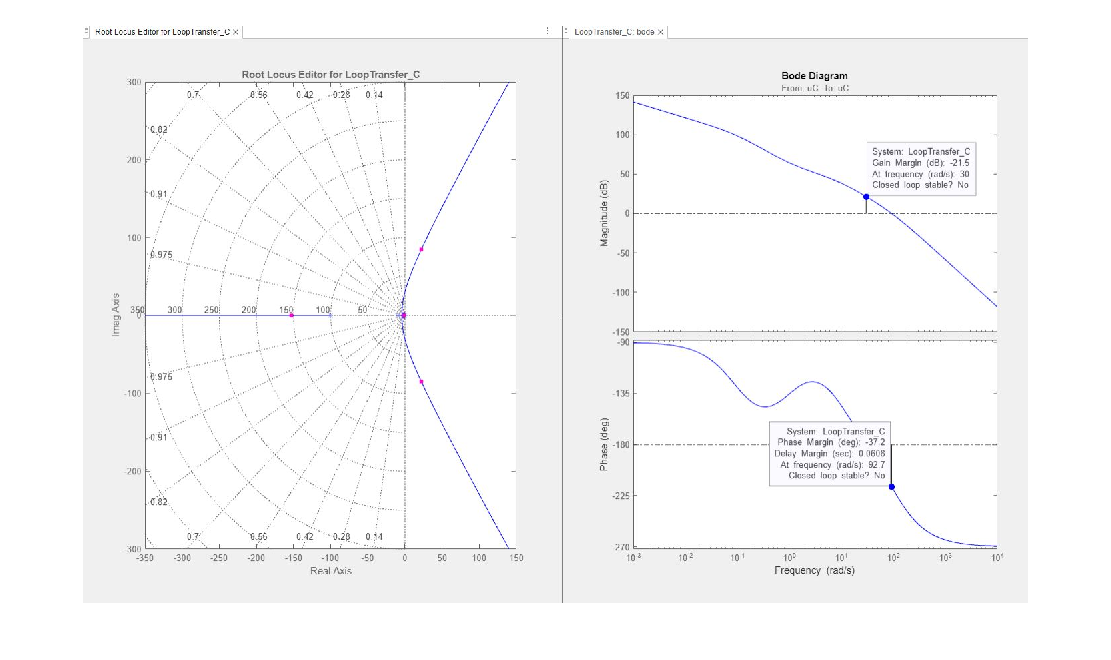


%margens de ganho e fase com um ganho K maior (K = 0.005)
figure;
imshow('K-005maior.jpg');

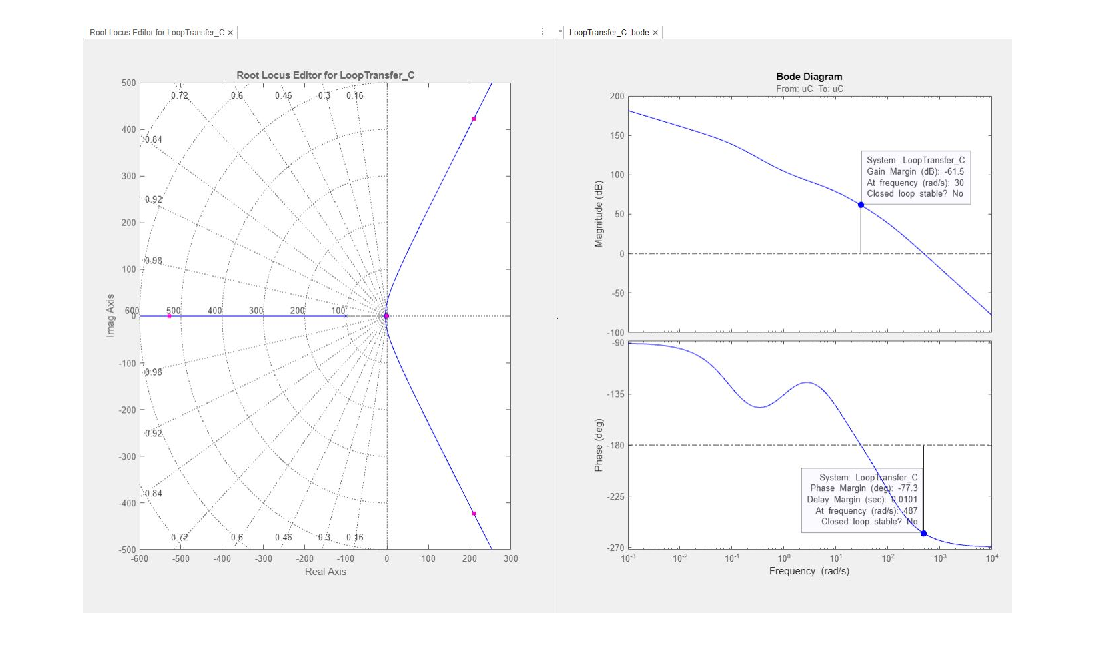



%margens de ganho e fase com um ganho K maior (K = 0.5)
figure;
imshow('K-05maior.jpg');

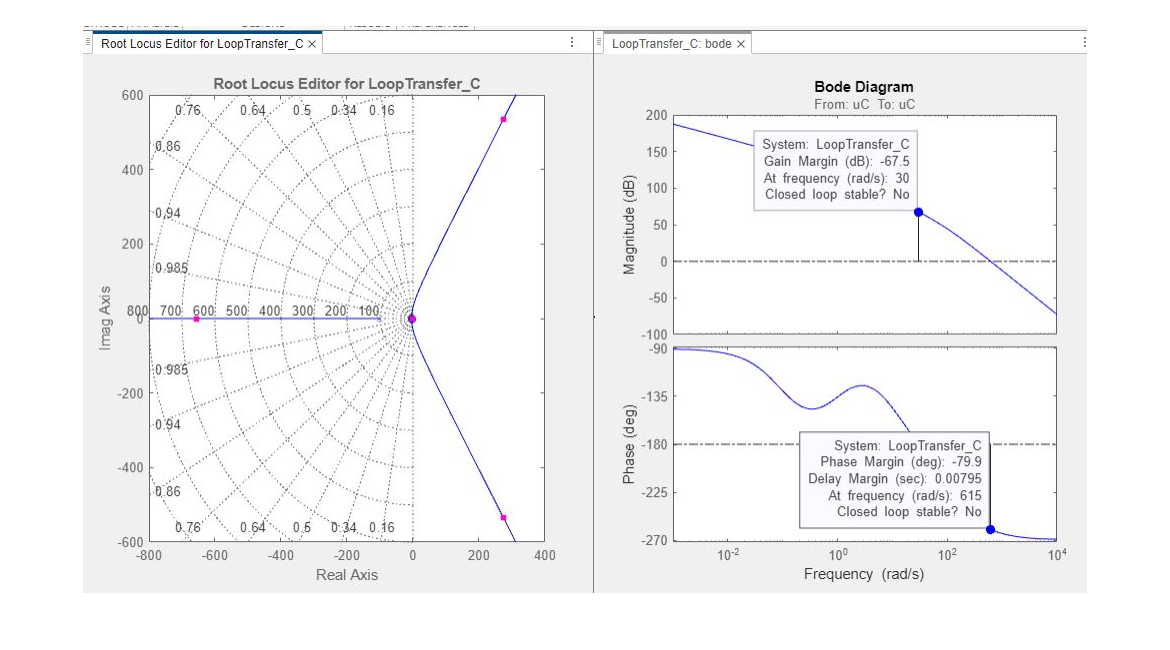



%margens de ganho e fase com um ganho K maior (K = 1)
figure;
imshow('K-1maior.jpg');

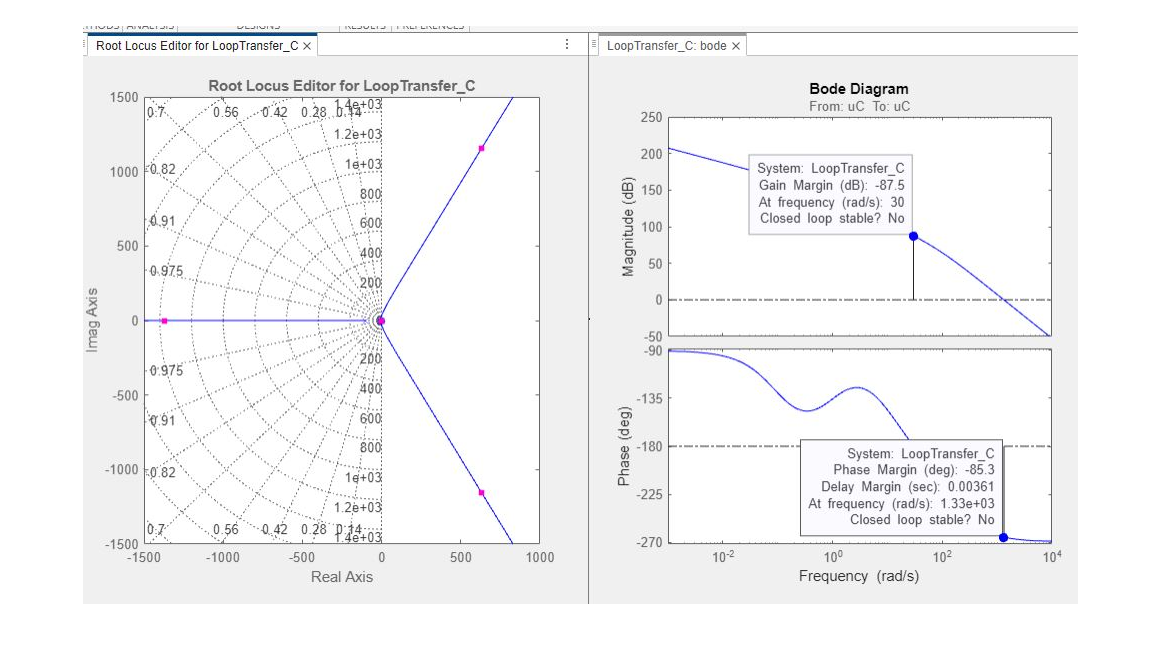


%margens de ganho e fase com um ganho K maior (K = 10)
figure;
imshow('K-10maior.jpg');

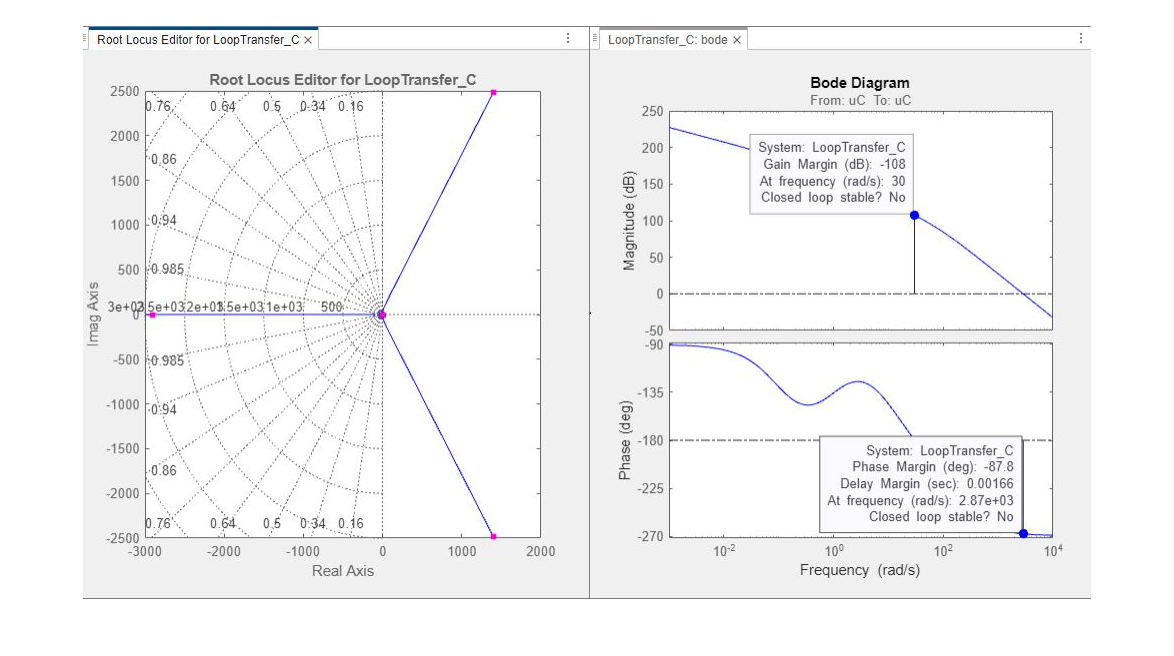


%margens de ganho e fase com um ganho K maior (K = 100)
figure;
imshow('K-muitomaior.jpg');

**Concluindo a Análise:**

Com base nas análises anteriores de nyquist e bode/margem (com amortecimento) de G1, é possivel destacar os seguintes comportamentos:

- Para Nyquist, o gráfico sempre estará antes do ponto -1, oque indica que sempre será estável independente do valor de K

- Para Bode, quando o ganho K aumenta as margens de fase e de ganho, o amortecimento diminui.

**3.2 Escolha um ganho K tal que a margem de fase seja aproximadamente 10 graus, mostrando o LR e o gráfico de Bode para este ganho K. Qual a margem de ganho ?**

O módulo permanece constante com o atraso no tempo (não sofre alteração), então analisando a margem de  fase é possivel determinar o atraso para aproximadamente MF =0.

Escolhendo um K = 0.000226, temos uma Margem de fase localizada em 21.8 rad/s de aproximadamente 10° e com uma margem de ganho de 5.39dB localizada em 30 rad/s

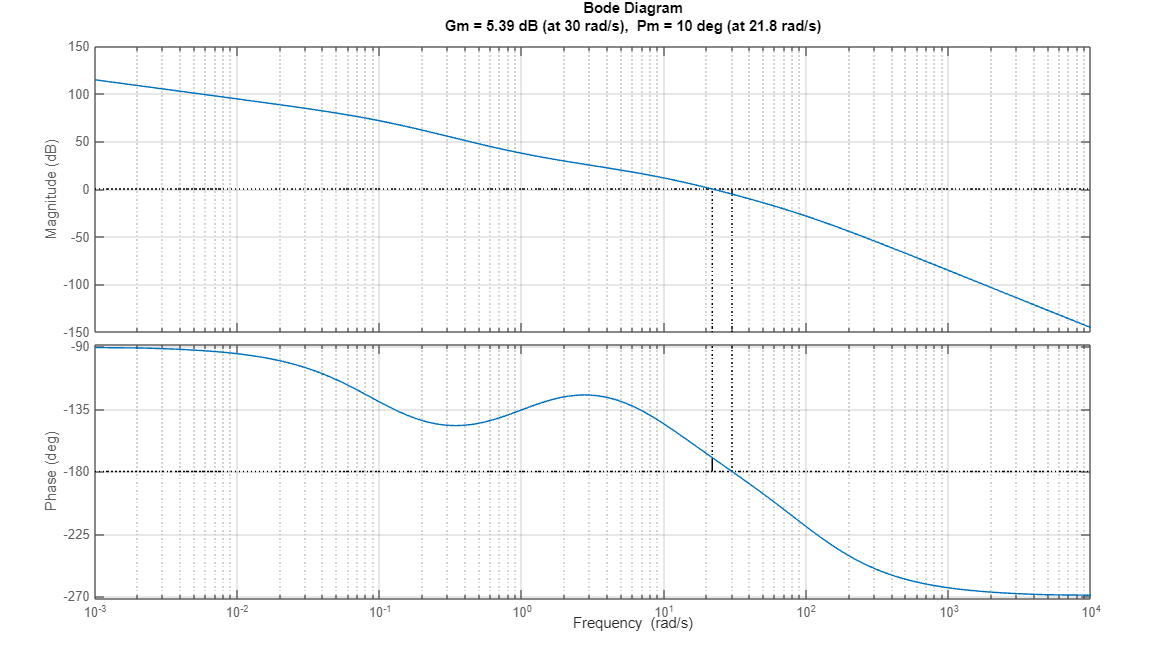


K_z = 0.000226;
margin(K_z*G1)
grid;

## Atividade 4: Efeito de um atraso de tempo na estabilidade relativa. 

4.1 Obtenha o atraso de tempo tal que G1 com este atraso tenha margem de fase nula.  Plote então o gráfico de Bode de G1 com e sem o atraso, verificando a margem de fase e de ganho nos dois casos.

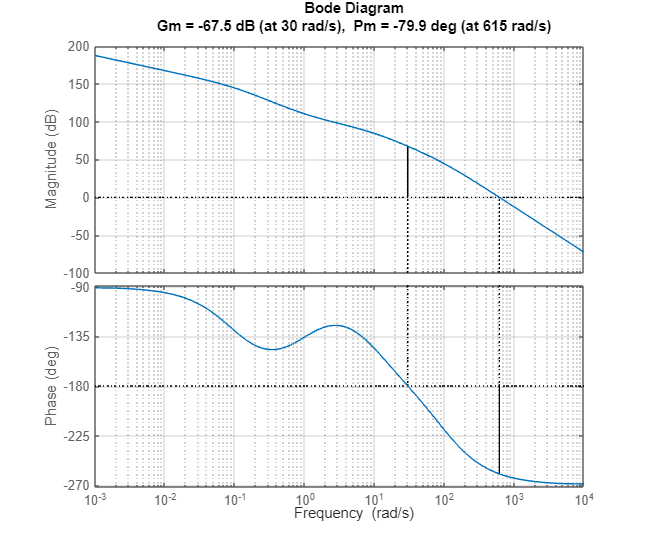


%plotando bode sem atraso
margin(G1)
grid;


%grid;

Análise:

Para obter uma Margem de Fase nula, é necessário introduzir um atraso de tempo na G1. Esse atraso deve ser ajustado de forma que, na frequência de cruzamento de ganho, o ângulo seja de -180 graus. Para isso, o atraso o atraso deve sermenor do que $d=\frac{\pi *\mathrm{MF}}{180*\omega }$�

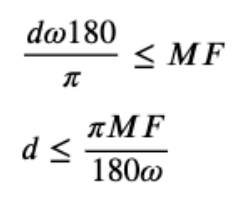

Onde MF e w  representam a margem de fase de G1 e a frequência de cruzamento de ganho, respectivamente.

Temos que MF=-79.9º em w=615 rad/s

Calculando:


$$\mathrm{delay}=\frac{\pi *-79\ldotp 9}{180*615}\;$$


pi = 3.14159265358979323846;
MF= 79.9; %MF é -79.9
Rads=615;  %Localizada em 615 Rad/s
delay=(pi*MF)/(180*Rads)

delay = 0.0023


%plotando bode com o atraso
Idelay = exp (-0.00795*s); %exp (-(-0.0023));
G1_DELAY = Idelay* G1

G1_DELAY =
 
                          2.358e08 s + 2.358e08
  exp(-0.00795*s) * ----------------------------------
                    s^4 + 110.1 s^3 + 1011 s^2 + 100 s
 
Continuous-time transfer function.
Model Properties


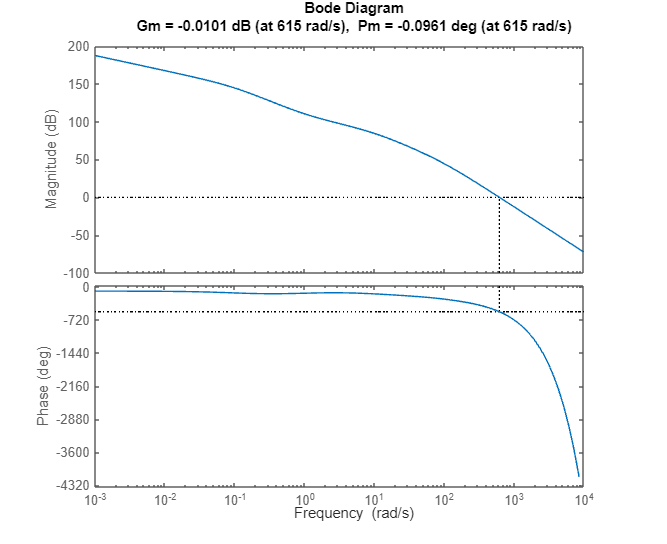

margin(G1_DELAY)

Podemos notar que, com d = 0.0023 não foi possível reduzir a margem a 0°, pois  para que o exp(-delay*s) não acusasse erro, eu tive que colocar o valor de MF positivo (+79.9) então isso resultou um um valor errado para a margem de fase, ao invés de reduzir a zero o seu valor, atrasou  o dobro.

**IMAGEM DO ERRO**

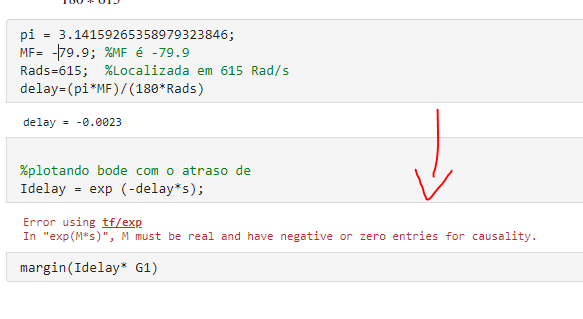

Caso não tivesse acusado erro, iria ocorrer o processo contrário, reduzindo assim o valor de 79.9 para próximo de zero.

No caso o valor $d=\frac{\pi *\mathrm{MF}}{180*\omega }$ seria -0.0023 e quando fosse para adicionar o effeito como no slide abaixo, o valor seria exp(-d*s) * G1 que resultaria na redução da fase para próximo de zero